## Experimento 3 - MP3 Player (Parte 1)

#### Bruno Hashimoto - 10715628

#### Guilherme Fernandes - 10297272

clear;
clc;

addpath(".", "functions/");

### 1.a) Gerando sinal chirp

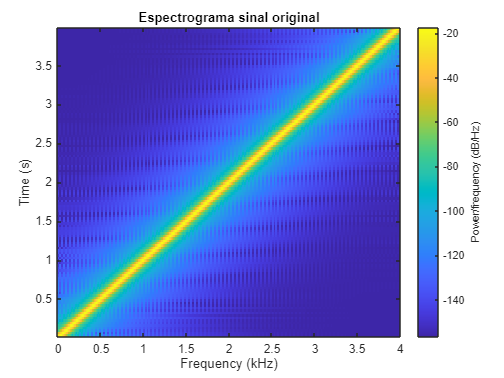

t_inicial = 0;
t_final = 4;
f_final = 4000;
f_a = 8000;

% funcao gera chirp implementada para utilizacao 
% nos proximos exercicios, disponivel na pasta 'functions'
[x,n] = gera_chirp(t_inicial, t_final, f_final, f_a);

figure;
spectrogram(x, hanning(512), 256, 1024, f_a);
title('Espectrograma sinal original');

### 1.b) 

Redução de taxa de amostragem por fator 2, seguida de aumento de amostragem pela mesma taxa

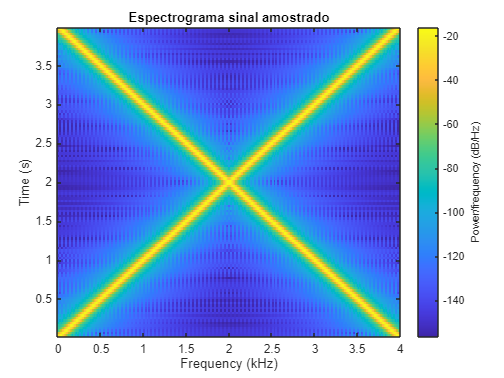

fator_amostragem = 2;

% implementacao das funcoes sub_amostragem e sobre_amostragem
% na pasta 'functions'
x_sub = sub_amostragem(x, fator_amostragem);
x_sobre = 2 * sobre_amostragem(x_sub, fator_amostragem);
% mult. por 2 para manter a potencia do sinal a mesma

figure;
spectrogram(x_sobre, hanning(512), 256, 1024, f_a);
title('Espectrograma sinal amostrado');

Ao ouvir o sinal original, escuta-se a frequência subindo linearmente. Já no sinal após sub-amostragem seguido de sobre-amostragem, escuta-se como se houvesse lacunas no sinal.

Uma comparação dos dois espectogramas auxilia na explicação dessa diferença. O que se verifica no espectrograma do sinal amostrado é que houve aliasing e rebatimento.

### 1.c) Implementação de filtro FIR passa-baixas

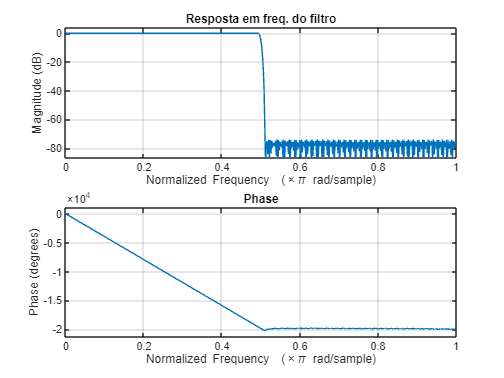

dev = [1e-4 2e-4];

[filter_order, fo, ao, w] = firpmord([1960 2040], [1 0], dev, f_a);
filter_coef = firpm(filter_order, fo, ao, w);

figure;
freqz(filter_coef, 1);
title('Resposta em freq. do filtro');

### 1.d) Espectograma do filtro passa baixas no sinal sobre amostrado

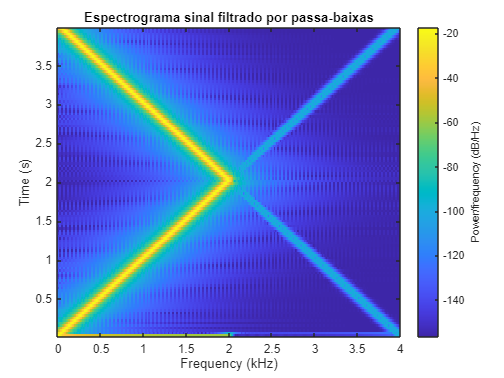

y = filter(filter_coef, 1, x_sobre);
figure;
spectrogram(y, hanning(512), 256, 1024, f_a);
title('Espectrograma sinal filtrado por passa-baixas');

O espectrograma indica o comportamento esperado, já que o filtro passa-baixas elimina as altas frequências do sinal. Para o sinal superamostrado se observa o mesmo sinal de antes, porém com as frequencias acima da frequencia de corte eliminadas. Além disso, verifica-se no canto inferior esquerdo um sinal, que é resultante do atraso gerado pelo filtro. 

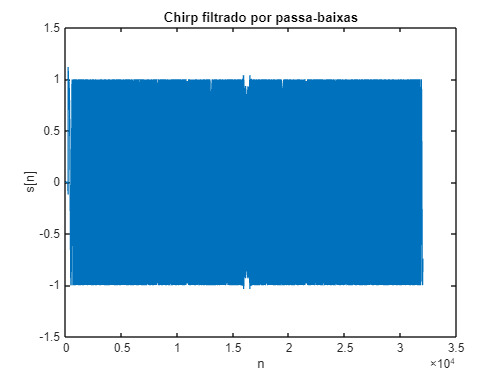

figure;
plot(n, y);
xlabel('n');
ylabel('s[n]');
title('Chirp filtrado por passa-baixas');

### 1.e) Proposta para evitar aliasing

Para evitar o aliasing, basta filtrar o sinal antes de fazer a sub-amostragem e super-amostragem, dessa forma evita-se o aliasing.

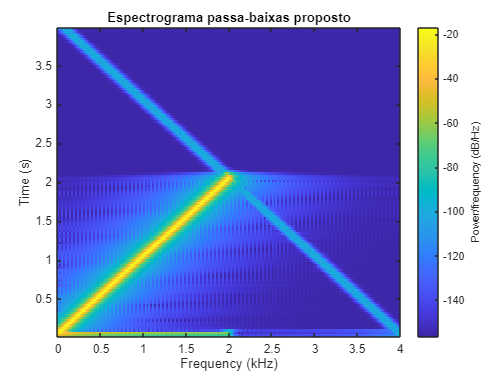

x_filt = filter(filter_coef, 1, x);

x_sub = sub_amostragem(x_filt, fator_amostragem);
x_sobre = 2*sobre_amostragem(x_sub, fator_amostragem);

x_lowpass = filter(filter_coef, 1, x_sobre);

figure;
spectrogram(x_lowpass, hanning(512), 256, 1024, f_a);
title('Espectrograma passa-baixas proposto');

O resultado acima, comprova a eficácia da proposta, no entanto, a informação de altas frequências do sinal é perdida.

### 1.f) Filtro passa altas

Para obter o espectro correspondente à banda de altas frequências basta utilizar um filtro passa-altas no sinal chirp. Primeiro obtém-se os coeficientes do filtro a partir do filtro passa-baixas.

filter_hp = real(filter_coef .* exp(pi*(0:filter_order)*i));

Seguindo a mesma linha do exercício anterior, agora com o filtro passa-altas.

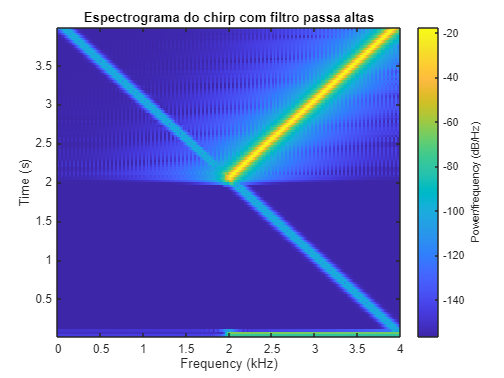

x_filt = filter(filter_hp, 1, x);

x_sub = sub_amostragem(x_filt, fator_amostragem);
x_sobre = 2*sobre_amostragem(x_sub, fator_amostragem);

x_highpass = filter(filter_hp, 1, x_sobre);

figure;
spectrogram(x_highpass, hanning(512), 256, 1024, f_a);
title('Espectrograma do chirp com filtro passa altas');

Observa-se que agora têm-se o caso complementar do exercício 1.e, o qual também inclui um atraso do filtro.

### 1.g) Combinação dos dois filtros

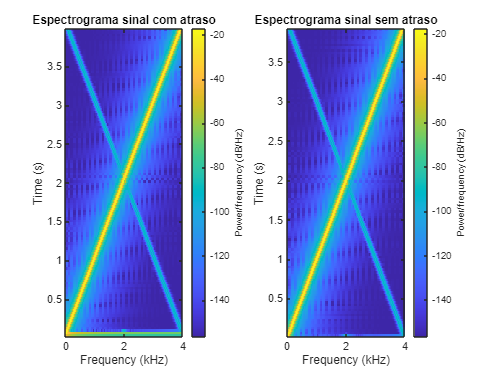

x_combinado = x_lowpass+x_highpass;

% correção do atraso
y_sem_atraso = x_lowpass(filter_order:end)+x_highpass(filter_order:end);

figure;
subplot(1,2,1);
spectrogram(x_combinado, hanning(512), 256, 1024, f_a);
title('Espectrograma sinal com atraso');
subplot(1,2,2);
spectrogram(y_sem_atraso, hanning(512), 256, 1024, f_a);
title('Espectrograma sinal sem atraso');

A combinação dos sinais torna possível a reconstrução do sinal sem aliasing.

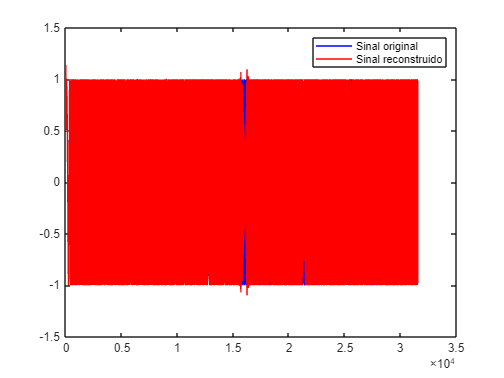

figure;
plot(x(1:end-filter_order), 'Color', 'blue');
hold on;
plot(y_sem_atraso, 'Color', 'red');
legend('Sinal original', 'Sinal reconstruido');